clear; close all; clc;

%% 1. CONFIGURATION & CHARGEMENT
filename = 'Circuits_Data/de-1927.geojson';
ds = 2.0; % Pas de discrétisation (mètres). Plus c'est petit, plus c'est précis mais lent.

% --- Paramètres du Véhicule (Type F1) ---
m = 750;           % Masse (kg)
P_max = 700000;    % Puissance Moteur (Watts) ~ 950ch
F_max = 25000;     % Force de traction max (N) (Pneus/Moteur à basse vitesse)
F_brake = 42000;   % Force de freinage max (N)
mu_lat = 1.9;      % Coefficient de friction latéral (Grip en virage)
g = 9.81;
a_lat_max = mu_lat * g; % Accélération latérale max (m/s^2)
v_top_speed = 340 / 3.6; % Vitesse max absolue (m/s)

%% 2. TRAITEMENT DE LA PISTE (Modelling Part)
fprintf('Chargement de la piste : %s...\n', filename);

Chargement de la piste : Circuits_Data/de-1927.geojson...



% A. Lecture du GeoJSON
try
    jsonText = fileread(filename);
    data = jsondecode(jsonText);
    
    % Extraction des coordonnées (Structure standard GeoJSON)
    % On cherche features -> geometry -> coordinates
    if isfield(data, 'features')
        raw_coords = data.features(1).geometry.coordinates;
    elseif isfield(data, 'geometry')
        raw_coords = data.geometry.coordinates;
    else
        error('Structure GeoJSON non reconnue. Vérifie le fichier.');
    end
    
    % GeoJSON est toujours [Lon, Lat]
    lon = raw_coords(:, 1);
    lat = raw_coords(:, 2);
catch ME
    error('Erreur lecture fichier. Vérifie que "%s" est dans le dossier.\n%s', filename, ME.message);
end

% B. Conversion Lat/Lon vers Mètres (Approximation Terre Plate locale)
lat0 = lat(1); lon0 = lon(1);
R_earth = 6371000; 
x_raw = R_earth * deg2rad(lon - lon0) * cos(deg2rad(lat0));
y_raw = R_earth * deg2rad(lat - lat0);

% Fermer la boucle si nécessaire (pour un circuit)
if sqrt((x_raw(1)-x_raw(end))^2 + (y_raw(1)-y_raw(end))^2) > 5
    x_raw(end+1) = x_raw(1);
    y_raw(end+1) = y_raw(1);
end

% ---------------------------------------------------------
% C. LISSAGE & NETTOYAGE (Correction Bug "Unique Values")
% ---------------------------------------------------------

% 1. Nettoyer les doublons (Points superposés)
% On calcule la distance carrée entre chaque point consécutif
d2 = diff(x_raw).^2 + diff(y_raw).^2;

% On garde le premier point, puis seulement ceux qui ont bougé (> 0)
% 1e-6 est une toute petite tolérance (1 mm) pour éviter les erreurs d'arrondi
is_moving = [true; d2 > 1e-6]; 

x_clean = x_raw(is_moving);
y_clean = y_raw(is_moving);

% 2. Recalculer la distance avec les points propres
dist_steps = sqrt(diff(x_clean).^2 + diff(y_clean).^2);
t_raw = [0; cumsum(dist_steps)]; % Distance curviligne stricte croissante

% 3. Création des splines cubiques (sur les données propres)
pp_x = spline(t_raw, x_clean);
pp_y = spline(t_raw, y_clean);

% 4. Ré-échantillonnage régulier
% On s'assure que ds ne dépasse pas la longueur totale
total_len = t_raw(end);
S = 0 : ds : total_len;

% Sécurité pour le dernier point (parfois l'arrondi fait dépasser S un tout petit peu)
if S(end) > total_len
    S(end) = total_len;
end

x_track = ppval(pp_x, S);
y_track = ppval(pp_y, S);

% D. Calcul de la Courbure (Curvature)
% Dérivées premières (Vitesse tangentielle géométrique)
dx = Gradient(x_track, ds);
dy = Gradient(y_track, ds);
% Dérivées secondes (Accélération géométrique)
ddx = Gradient(dx, ds);
ddy = Gradient(dy, ds);

% Formule de la courbure k = (x'y'' - y'x'') / (x'^2 + y'^2)^1.5
curvature = (dx .* ddy - dy .* ddx) ./ (dx.^2 + dy.^2).^(1.5);
curvature(isnan(curvature)) = 0;

%% 3. OPTIMISATION (Forward-Backward Integration)
fprintf('Calcul de l''optimisation...\n');

Calcul de l'optimisation...



N = length(S);

% --- Étape 1 : Vitesse Limite Statique (Virages) ---
% v <= sqrt( a_lat_max / |k| )
v_limit = sqrt(a_lat_max ./ (abs(curvature) + 1e-5)); 
v_limit = min(v_limit, v_top_speed); % Plafonner à la Vmax de la voiture

% --- Étape 2 : Passe Avant (Accélération) ---
v_fwd = zeros(1, N);
v_fwd(1) = 0; % Départ arrêté

for i = 1:N-1
    % Force moteur dispo (limitée par grip ou puissance)
    % F = min(F_max, P/v)
    v_curr = max(v_fwd(i), 1); % Éviter division par 0
    F_avail = min(F_max, P_max / v_curr);
    
    a_long = F_avail / m;
    
    % v^2_final = v^2_initial + 2*a*d
    v_next = sqrt(v_fwd(i)^2 + 2 * a_long * ds);
    
    % Appliquer la contrainte de virage du prochain point
    v_fwd(i+1) = min(v_next, v_limit(i+1));
end

% --- Étape 3 : Passe Arrière (Freinage) ---
v_bwd = zeros(1, N);
v_bwd(N) = 0; % On s'arrête à la fin (ou v_limit(N) pour un tour lancé)

for i = N:-1:2
    % Freinage max
    a_brake = F_brake / m;
    
    v_prev = sqrt(v_bwd(i)^2 + 2 * a_brake * ds);
    
    % Appliquer contrainte virage
    v_bwd(i-1) = min(v_prev, v_limit(i-1));
end

% --- Étape 4 : Solution Finale ---
v_final = min(v_fwd, v_bwd);
T_total = sum(ds ./ max(v_final, 1)); % Temps total approximatif

%% 4. VISUALISATION
fprintf('Terminé. Temps au tour estimé : %.2f s\n', T_total);

Terminé. Temps au tour estimé : 103.19 s


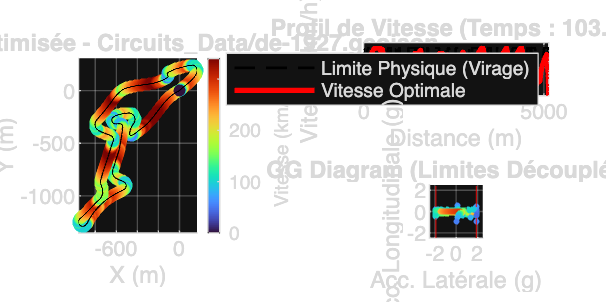


figure('Name', 'F1 Optimization Project', 'Color', 'w', 'Position', [100 100 1200 600]);

% Carte du Circuit
subplot(2,2,[1 3]);
scatter(x_track, y_track, 20, v_final*3.6, 'filled'); hold on;
plot(x_track, y_track, 'k', 'LineWidth', 0.5);
c = colorbar; c.Label.String = 'Vitesse (km/h)';
colormap turbo; % 'jet' si turbo n'existe pas sur ta version
axis equal; grid on;
title(['Trajectoire Optimisée - ' filename], 'Interpreter', 'none');
xlabel('X (m)'); ylabel('Y (m)');

% Profil de Vitesse
subplot(2,2,2);
plot(S, v_limit*3.6, 'k--', 'LineWidth', 1); hold on;
plot(S, v_final*3.6, 'r-', 'LineWidth', 2);
legend('Limite Physique (Virage)', 'Vitesse Optimale');
xlabel('Distance (m)'); ylabel('Vitesse (km/h)');
title(['Profil de Vitesse (Temps : ' num2str(T_total, '%.1f') 's)']);
grid on; ylim([0 380]);

% GG Diagram
subplot(2,2,4);
% Calcul des accélérations réelles subies
acc_long = diff([0 v_final]).^2 / (2*ds); % a = dv^2/2ds
% Signe de l'accélération (Accél ou Frein)
is_braking = diff([0 v_final]) < 0;
acc_long(is_braking) = -acc_long(is_braking);
acc_lat = v_final.^2 .* curvature;

scatter(acc_lat/g, acc_long/g, 5, v_final*3.6, 'filled');
xlabel('Acc. Latérale (g)'); ylabel('Acc. Longitudinale (g)');
title('GG Diagram (Limites Découplées)');
axis square; grid on;
xline([-mu_lat mu_lat], '--r'); 
yline([F_max/m/g -F_brake/m/g], '--r');
xlim([-2.5 2.5]); ylim([-2.5 2.5]);



%% FONCTION UTILITAIRE LOCALE
function d = Gradient(f, ds)
    % Différences finies centrées pour calculer la dérivée
    n = length(f);
    d = zeros(size(f));
    d(1) = (f(2) - f(1))/ds;
    d(n) = (f(n) - f(n-1))/ds;
    d(2:n-1) = (f(3:n) - f(1:n-2))/(2*ds);
end